# Enviroment representation

The following pseudo code will help you to recreate the enviroment as Rosa Robot does.

Moreover will help you in understant all the transformation algebra needed to manage the information.

Keep in mind: 

a) Rosa Robot touch the fiducial and this allow to the system to know the the fiducial coordinates wrt RF {R}

b) From Dicom image you know the fiducial coordinates wrt RF {I}

c) Use a new RF {F} as an intermediate RF among both (Fiducial wrt {I} and Fiducial wrt {R})

d) Then you already have all the Transformation to given Tumor wrt RF{I} to know Tumor coordiantes wrt {R}

## Given enviroment

Given the table with the patient in an arbitrary pose. Use your previous deliverables.

In fact only fiducials are needed

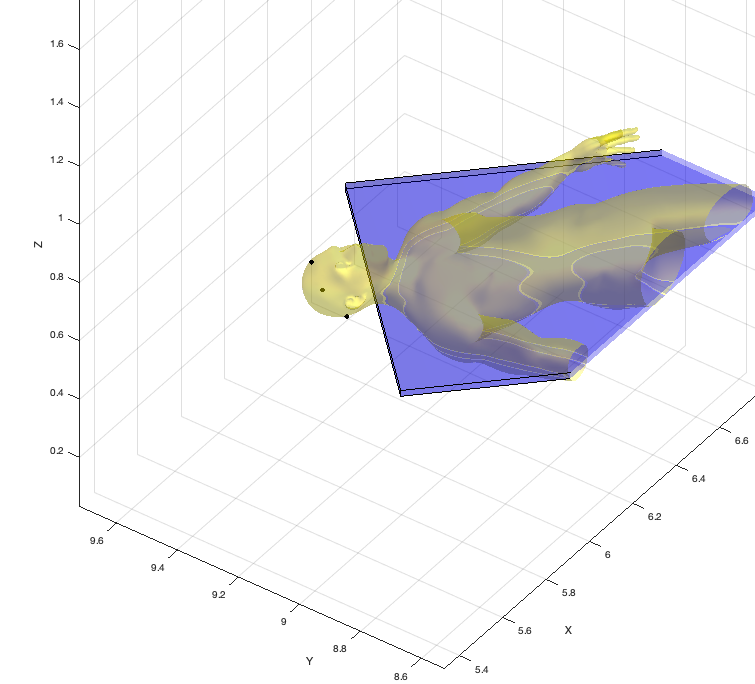

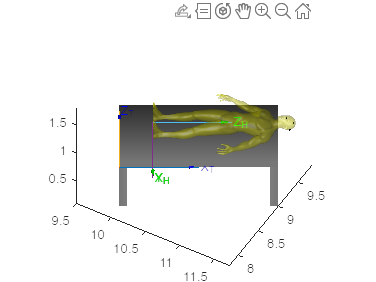

clear
close all
clf

T_M_U = transl(10,8,0.8)*trotz(pi/6); % Reference Frame Taula

v_ini= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1];
LDH = [2 0 0; 0 1 0; 0 0 0.1];
v = v_ini * LDH;
v = [v ones(size(v,1),1)];
v = (T_M_U * v')';
f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];

mesa = figure;
figure(mesa);
patch('Vertices',v(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
view(30,45)
axis equal

v_pata = v_ini * [0.1 0 0; 0 0.1 0; 0 0 0.7];
v_pata = [v_pata ones(size(v_pata,1),1)];

v_pata1 = (T_M_U * transl(0,0,-0.7) * v_pata')';
v_pata2 = (T_M_U * transl(1.9,0,-0.7) * v_pata')';
v_pata3 = (T_M_U * transl(1.9,0.9,-0.7) * v_pata')';
v_pata4 = (T_M_U * transl(0,0.9,-0.7) * v_pata')';

patch('Vertices',v_pata1(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
patch('Vertices',v_pata2(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
patch('Vertices',v_pata3(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
patch('Vertices',v_pata4(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)


camlight('headlight')
material('dull')
view(30,45)
axis equal
hold on

trplot(T_M_U, 'frame', 'T', 'length', 1, 'arrow', 'color', 'b');

load("F_V_HumanBody.mat")

T_H_M = T_M_U * transl(0.42,0.5,0.3) * troty(pi/2) * trotz(-pi/2); % Reference Frame Humà wrt Taula
v_human = [Vh ones(size(Vh, 1),1)];
v_human = (T_H_M * v_human')';

patch('Vertices',v_human(:,(1:3)),'Faces',Fh,'FaceVertexCData',hsv(6),'FaceColor','y', 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
axis equal

trplot(T_H_M,'frame', 'H', 'length', 1, 'arrow', 'color', 'g');

F1_I = [0.06656 0.200 0.112 1]';
F2_I = [0.186 0.209 0.0658 1]';
F3_I = [0.122 0.062 0.0252 1]';

[X,Y,Z] = sphere;

r2 = 0.005;

X3 = X * r2;
Y3 = Y * r2;
Z3 = Z * r2;

T_I_H = T_H_M * troty(pi) * transl(-(0.0765+0.041),-(0.1136+0.026),-(1.65+0.15)); % Reference Frame Imagen wrt Humà modificar para que quede como DICOM
T_F_I = T_I_H *  troty(-pi) * transl(-0.235,0,-0.14);

F1_U = T_F_I * F1_I;

surf(X3+F1_U(1,1),Y3+F1_U(2,1),Z3+F1_U(3,1),'FaceColor',[1 0 0])
axis equal

F2_U = T_F_I * F2_I;
surf(X3+F2_U(1,1),Y3+F2_U(2,1),Z3+F2_U(3,1),'FaceColor',[1 0 0])
axis equal

F3_U = T_F_I * F3_I;

surf(X3+F3_U(1,1),Y3+F3_U(2,1),Z3+F3_U(3,1),'FaceColor',[1 0 0])
axis equal


triangle = [F1_U(1:3,:), F2_U(1:3,:), F3_U(1:3,:)];

AB = (triangle(1:3,1) - triangle(1:3,2)) / norm(triangle(1:3,1) - triangle(1:3,2)); % Vector pointing A 
CB = (triangle(1:3,3) - triangle(1:3,2)) / norm(triangle(1:3,2) - triangle(1:3,3)); % Vector pointing C
Z_B = cross(CB, AB) / norm(cross(CB, AB));

orientAB = oa2r(AB, Z_B);
T_F_F = [orientAB F2_U(1:3); 0 0 0 1];


hold on

## Robot Frame wrt {U}

The Robot Rosa is located near by the patient 

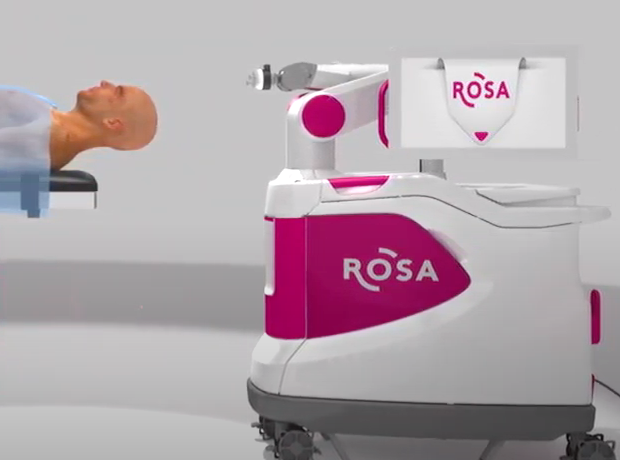

Locating the Robot. Understand the code

robot_loation=transl(5.75,9.75,0)*trotz(-pi/4)

robot_loation =     0.7071    0.7071         0    5.7500
   -0.7071    0.7071         0    9.7500
         0         0    1.0000         0
         0         0         0    1.0000


mdl_puma560;
p560.base=robot_loation

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (5.75, 9.75, 0), RPY/xyz = (-45, 0, 0) deg          
 


p560.plot(qr,'zoom',1.5)
axis([5 6.5 8.8 10 0 1.8])

T_R_U=p560.base.T

T_R_U =     0.7071    0.7071         0    5.7500
   -0.7071    0.7071         0    9.7500
         0         0    1.0000         0
         0         0         0    1.0000


## Fiducial wrt {U}

To emulate the action of measuring the fiducial wrt Robot Frame use your fiducials coordinate wrt {U}.

% Declare your fiducial coordinates
% F1= image 94
F1_U = T_F_I * F1_I;
% F2= image 32
F2_U = T_F_I * F2_I;
% F3= image 65
F3_U = T_F_I * F3_I;

## Transform compound needed

We will need the following Reference Frames: {U}, {R}, {F}, {I} 

and the Following Transformation: $ {}_R^U{T,{}_F^R{T,{}_I^F{Tand{}_I^R{T$to correctly face the problem.

It is clear that we will need the transformation Image to Robot, i.e. ${}_I^R{T$ to correctly make the tumor surgery.

Remeber the doctor, based on the Dicom image locate the Tumor (i.e Reference Image {I}) .

## Fiducial in RF Robot {R}

Notice: You have fiducial in RF {U}={A } and you want it in RF{R}={B} ... So  ${}^BP = {}_B^A{T^{ - 1}}{}^AP$

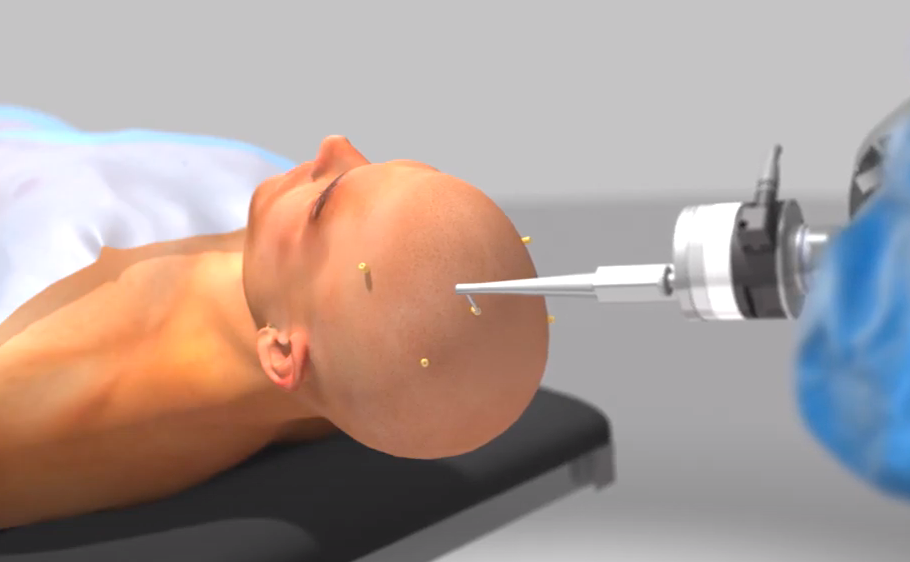

%T_R_F = inv(T_R_U) * T_F_U

% Fi_R=inv(T_R_U)*[F1 F2 F3;ones(1,3)]
%F1_R = inv(T_R_F) * F1_U;
% F2= image 32
%F2_R = inv(T_R_F) * F2_U;
% F3= image 65
%F3_R = inv(T_R_F) * F3_U;

## RF Fiducial {F} wrt RF {R}

It is needed to use an auxiliary Reference Frame formed by the three fiducials becouse they are measured by the Robot using the teach Tool (See above section) and the Computed Tomography (Dicom images).

We will use the fiducials in RF {R}

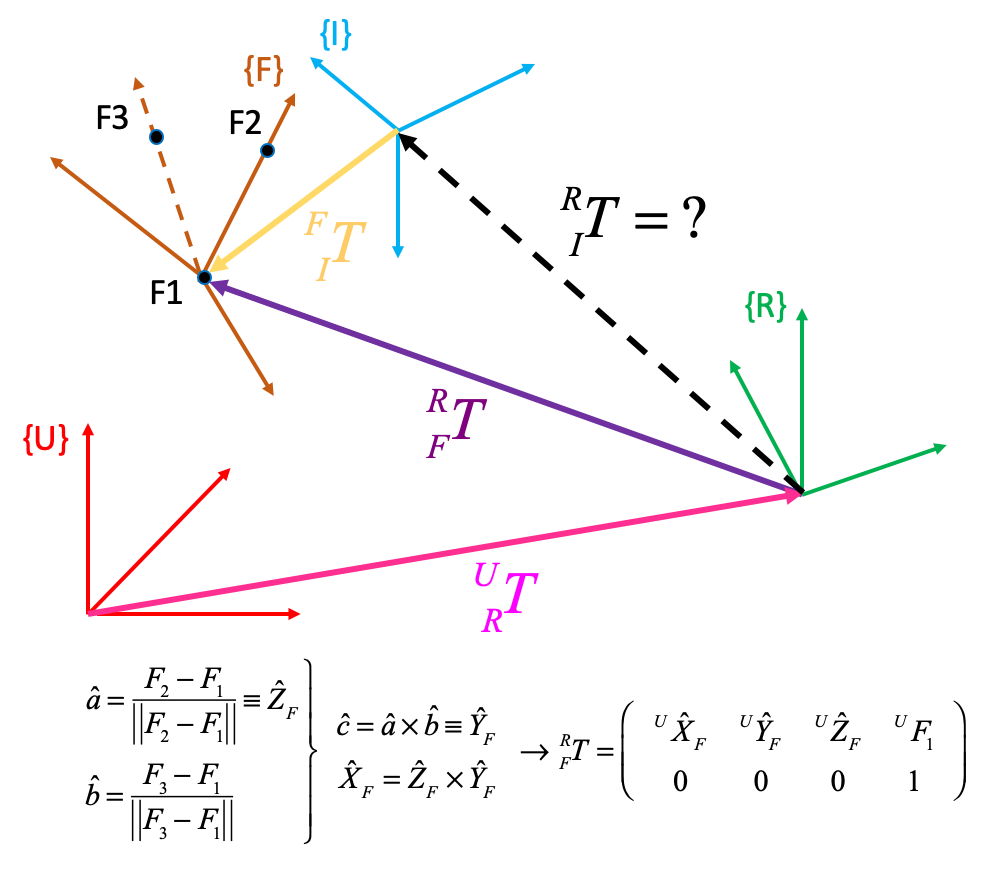

### Orientation wrt {R}

As a matter the example. 

%Yf = (Fi_R(1:3,?)-Fi_R(1:3,?))/norm(Fi_R(1:3,?)-Fi_R(1:3,?));
%b=(Fi_R(1:3,?)-Fi_R(1:3,?))/norm(Fi_R(1:3,?)-Fi_R(1:3,?));
%Zf = cross(Yf,b)/norm(cross(Yf,b));
%Xf = cross(Yf,Zf)/norm(cross(Yf,Zf));
Zf = (F2_U - F1_U) / det(F2_U - F1_U)
b =  (F3_U - F1_U) / det(F3_U - F1_U)
Yf = cross(Zf,b)/norm(cross(Zf,b));
Xf = cross(Zf,Yf)/norm(cross(Zf,Yf));
%para hacer el T_F_R solo hace falta juntar los valores
T_F_R = [Xf Yf Zf F_U?; 0 0 0 1]


### Hand made frame description   

${}_F^R{T$ take the Fiducial 1 as ${}^A{P_{BORG}}$ in our case A is RF{R}

%T_F_R = [[Xf;0] [Yf;0] [Zf;0] [Fi_R(:,3)]]
F1_R = T_F_R * F1_U

Checking the rotation matrix

The determinan must be 1

% det(T_F_R(1:3,1:3))

## RF Fiducial {F} wrt RF {U}

The answer to this question is ${}_F^U{T={}_R^U{T{}_F^R{T$

We needed  ${}_F^U{T$to draw it in RF {U}

%T_F_U=T_R_U*T_F_R
%trplot(T_F_U,'Frame','F','color', 'b','length',0.4)

## Fiducials wrt {I} 

Taking data from Dicom images

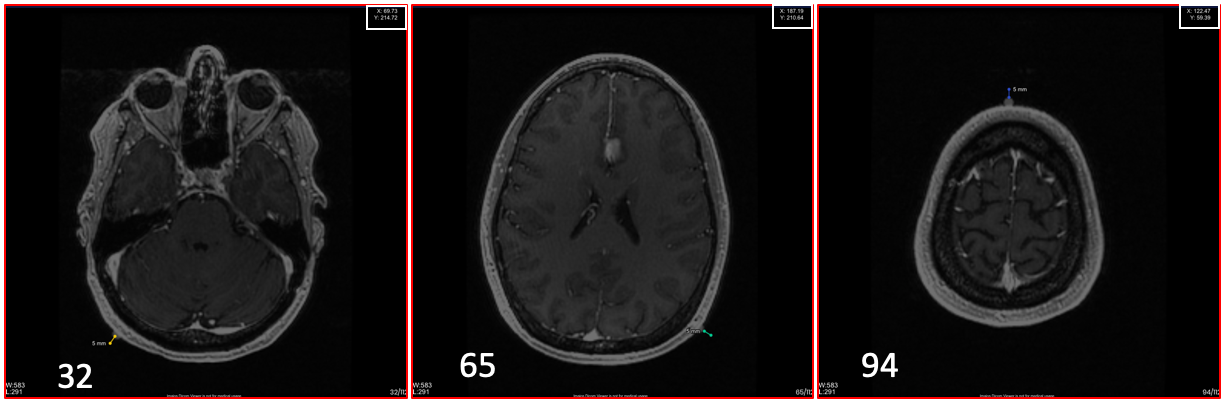

% pitch =1.4; % Pitch among slices 
% F1D = [xx yy 0.032*pitch]'; %image #32
% F2D = [xx yy 0.065*pitch]'; %image #65
% F3D = [xx yy 0.094*pitch]'; %image #94
% Tumor=[xx yy 0.078*pitch]';%image #78

## Visualizing fiducials and tumor

Use your previous deliverables

### Image Frame 

Plotting Image Reference Frame at origen of Reference Frame Univers {U}

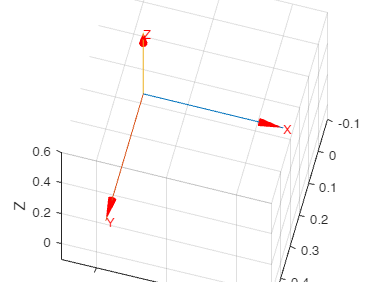

figure
trplot(eye(3),'Frame','I','color', 'r','length',0.4, 'arrow','width',0.4)
hold on
axis([-0.1 0.5 -0.1 0.5 -0.1 0.6])
view (-15,-65) % For better understanding

### Fiducials and tumor in {I} 

We use a sphere to represent a fiducial

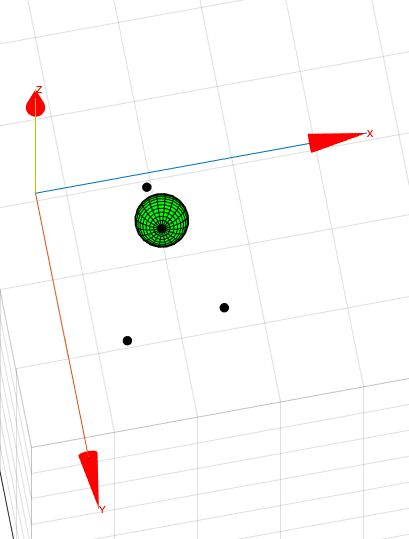

% put your code here

## T_F_I - Frame Description 

As we mention before It is needed to use the Fiducial as auxiliary Reference Frame 

Extracted from the triangle F1D - F2D - F3D

Same procedure as before with the fiducial in RF {U}

### Orientation 

### Frame Description  

${}_F^I{T$ take the Fiducial 1 as ${}^A{P_{BORG}}$ in our case A is RF{I}

% T_F_I = [[XfD;0] [YfD;0] [ZfD;0] [F3D;1]]
%det(T_F_I)

### Visualizing T_F_I

Fiducial Reference Frame wrt Reference frame {I} at origen of {U}

%trplot(T_F_I,'Frame','F','color', 'b','length',0.4)

## RF Image {I} wrt RF {U}

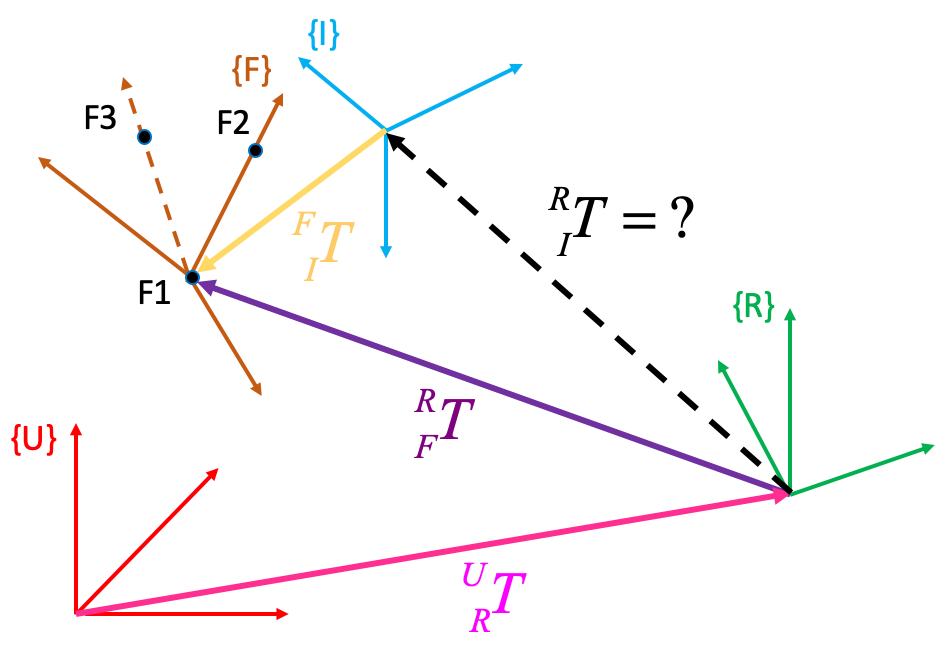

We have the Reference Frame {F} wrt {U} ${}_F^U{T={}_R^U{T{}_F^R{T$ and also ${}_F^I{T $, so ... ${}_I^U{T={}_F^U{T{}_F^I{T^{-1}$

%T_I_U=T_F_U*inv(T_F_I)

Ckeck that ${}_I^U{T$ is coincident with the given Image Reference Frame 

%trplot(T_I_U,'Frame','I','color', 'cyan','length',0.7)

## T_I_R System equation


$$ {}_I^U{T={}_F^U{T{}_F^I{T^{-1}={}_R^U{T{}_I^R{T\\
{}_I^R{T={}_R^U{T^{-1}{}_F^U{T{}_F^I{T^{-1}$$


%T_I_R=inv(T_R_U)*T_F_U*inv(T_F_I)

## Overall ckecking

### Fiducials in Robot Frame

As a matter of proof, ckeck that given Fiducials coordinates in Image Reference Frame we can obtain them in Robot Reference Frame

%Fi_R2=T_I_R*[[F1D F2D F3D];ones(1,3)]
%Fi_R

### Fiducials in Univers Frame

As a matter of proof, ckeck that given Fiducials coordinates in Image Reference Frame we can obtain them in Univers Reference Frame.

%Fi_R2=T_R_U*T_I_R*[[F1D F2D F3D];ones(1,3)]

## Summary

a) Rosa Robot touch the fiducial and this allow to the system to know the the fiducial coordinates wrt RF {R}

b) From Dicom image you know the fiducial coordinates wrt RF {I}

c) Use a new RF {F} as an intermediate RF among both (Fiducial wrt {I} and Fiducial wrt {R})

d) Then you already have all the Transformation to given Tumor wrt RF{I} to know Tumor coordiantes wrt {R}

e) You can draw tumor, containing box, human and table and you can represent all the RF's

## How I will ckeck 

Next Laboratory session I will give you the Rosa Robot information: i.e the Fiducials coordinates in RF {R}

and you will have to recreate all the enviroment. (containing box, human, table and all RF's)

There will be no second round, that is, I will mark your result.